**Functions to Test from Assignment**

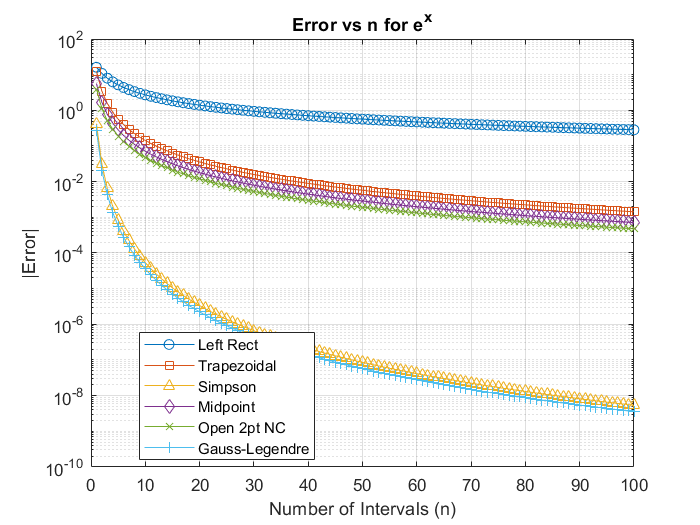

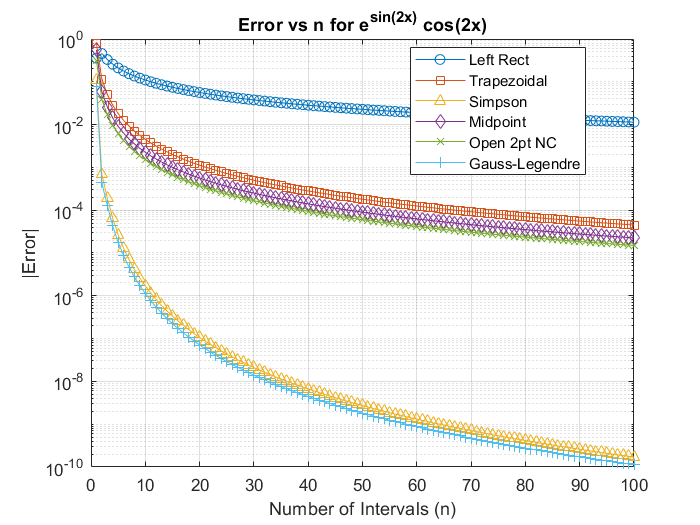

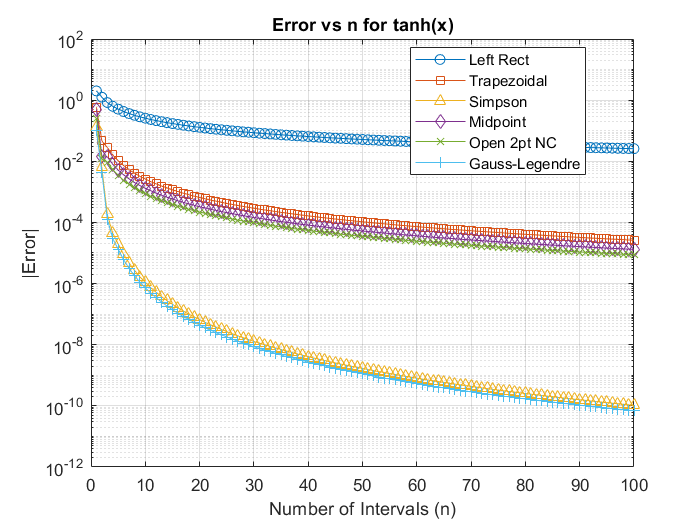

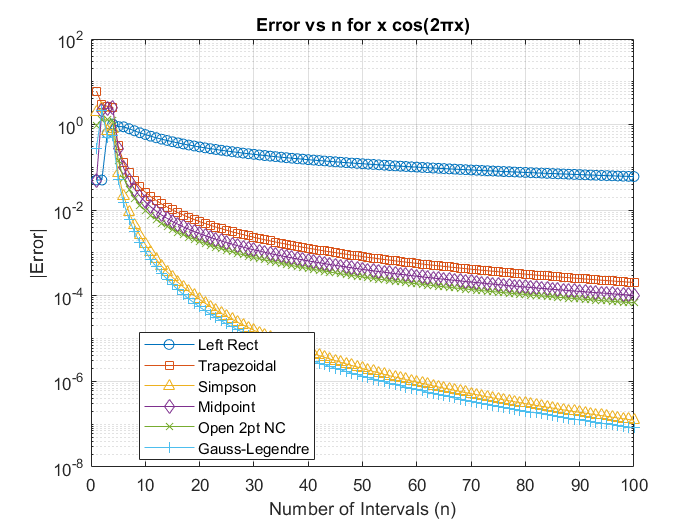

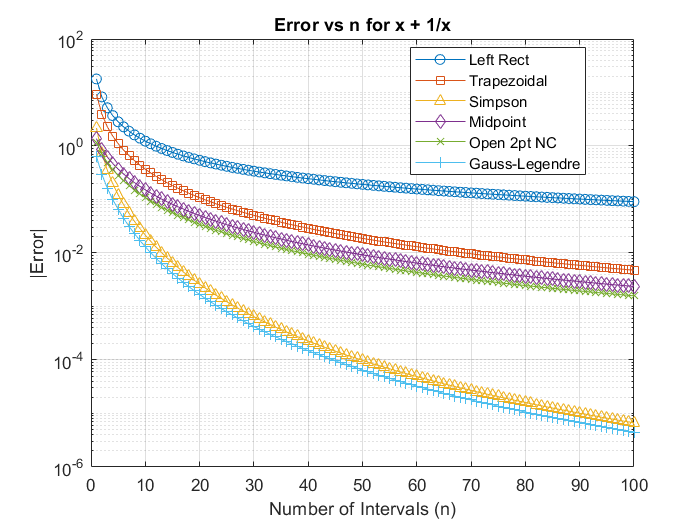

% List of functions and exact values
functions = {
    @(x) exp(x),                        0, 3,              exp(3) - 1,                         'e^x';
    @(x) exp(sin(2*x)).*cos(2*x),       0, pi/3,           0.5 * (-1 + exp(sqrt(3)/2)),        'e^{sin(2x)} cos(2x)';
    @(x) tanh(x),                      -2, 1,              log(cosh(1)/cosh(2)),               'tanh(x)';
    @(x) x .* cos(2*pi*x),              0, 3.5,            -1/(2*pi^2),                        'x cos(2πx)';
    @(x) x + 1./x,                      0.1, 2.5,          (2.5^2 - 0.1^2)/2 + log(2.5/0.1),    'x + 1/x'
};

N = 1:100;
numFuncs = size(functions, 1);
errors = struct();

% Loop through each function
for k = 1:numFuncs
    f = functions{k,1};
    a = functions{k,2};
    b = functions{k,3};
    true_val = functions{k,4};
    label = functions{k,5};
    
    % Initialize error arrays
    err_left = zeros(size(N));
    err_trap = zeros(size(N));
    err_simp = zeros(size(N));
    err_mid  = zeros(size(N));
    err_open = zeros(size(N));
    err_gauss = zeros(size(N));
    
    for i = 1:length(N)
        n = N(i);
        mesh = linspace(a, b, n+1);
        H = (b - a)/n;

        [~, err_left(i)]  = leftrectangle(f, mesh, H, n, true_val);
        [~, err_trap(i)]  = trapezoidal(f, mesh, H, n, true_val);
        [~, err_simp(i)]  = simpson(f, mesh, H, n, true_val);
        [~, err_mid(i)]   = midpoint(f, mesh, H, n, true_val);
        [~, err_open(i)]  = opentwopoint(f, mesh, H, n, true_val);
        [~, err_gauss(i)] = gausslege(f, mesh, H, n, true_val);
    end
    
    % Store errors
    errors(k).name = label;
    errors(k).left = abs(err_left);
    errors(k).trap = abs(err_trap);
    errors(k).simp = abs(err_simp);
    errors(k).mid  = abs(err_mid);
    errors(k).open = abs(err_open);
    errors(k).gauss = abs(err_gauss);
    
    % Plot
    figure;
    semilogy(N, abs(err_left), '-o', ...
             N, abs(err_trap), '-s', ...
             N, abs(err_simp), '-^', ...
             N, abs(err_mid),  '-d', ...
             N, abs(err_open), '-x', ...
             N, abs(err_gauss),'-+');
    legend('Left Rect', 'Trapezoidal', 'Simpson', 'Midpoint', 'Open 2pt NC', 'Gauss-Legendre', ...
           'Location', 'best');
    xlabel('Number of Intervals (n)');
    ylabel('|Error|');
    title(['Error vs n for ', label]);
    grid on;
    
    % Sanitize label for file name
    filename = regexprep(label, '[^a-zA-Z0-9]', '_');  % Replace non-alphanumeric characters with "_"
    filename = ['fine_error_plot_' filename '.png'];

    % Save the figure
    saveas(gcf, filename);
end

**Degree of Exactness**

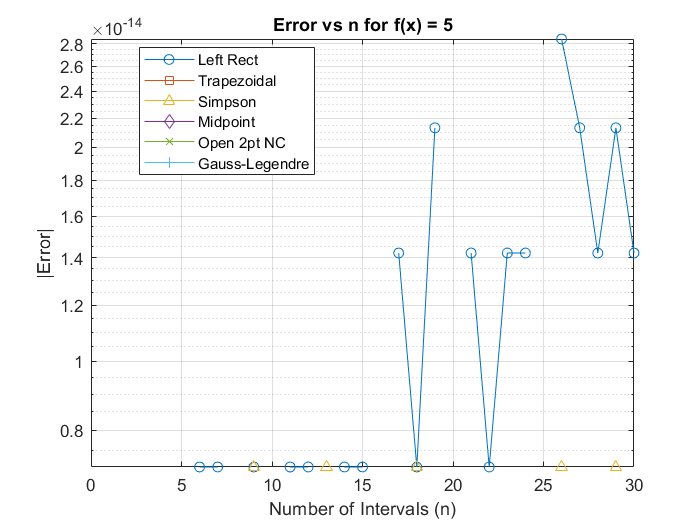

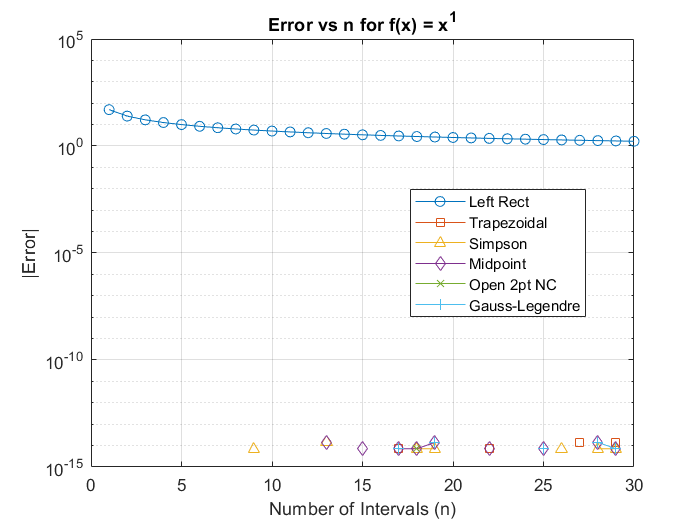

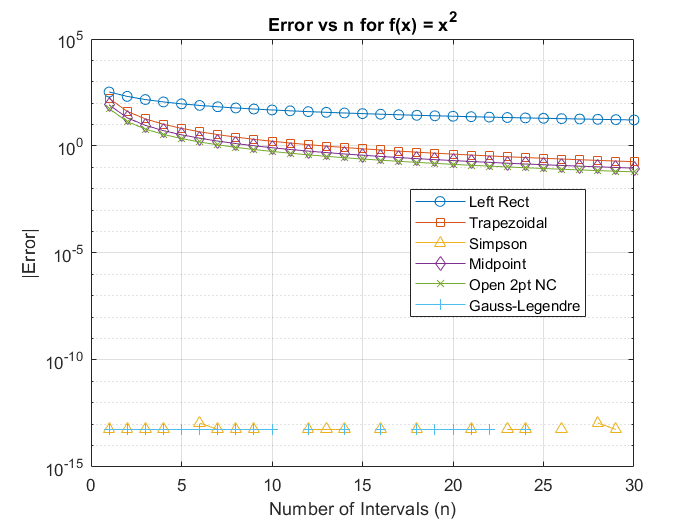

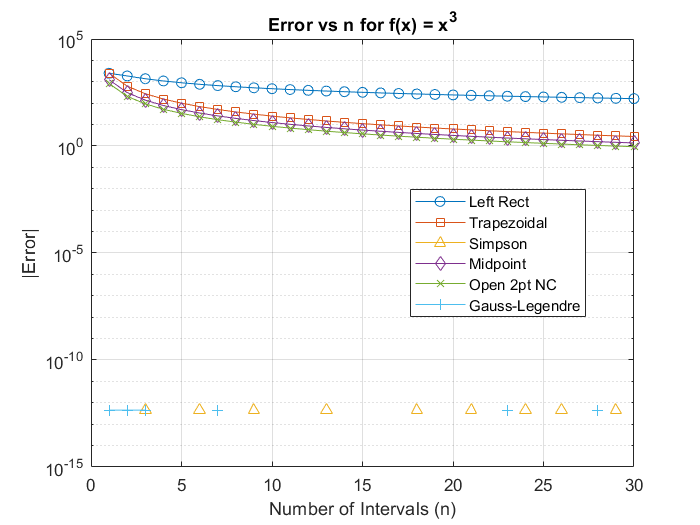

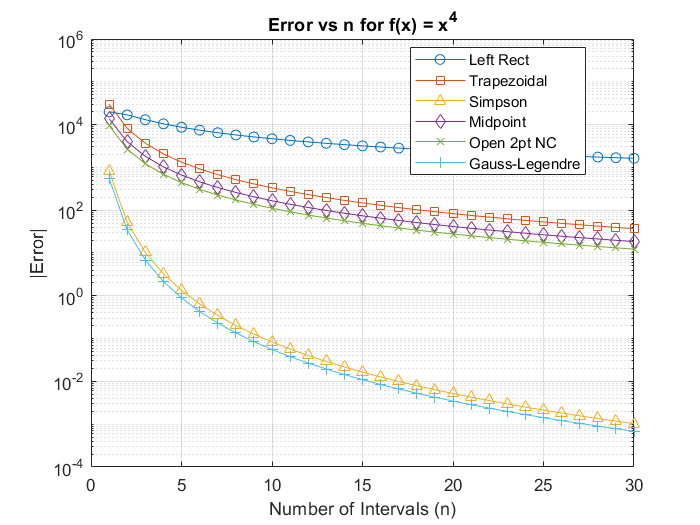

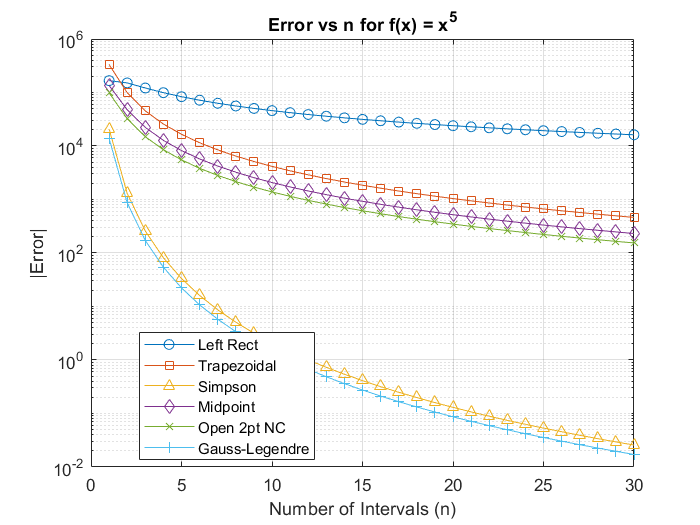

% Degrees to test including constant function (degree = 0)
degrees = 0:5;
a = 0;
b = 10;
N = 1:30;

for d = degrees
    if d == 0
        f = @(x) 5 + 0.*x;                      % Constant function
        true_val = 5 * (b - a);                 % Integral of constant over [a, b]
    else
        f = @(x) x.^d;
        true_val = b^(d+1) / (d + 1);
    end

    % Initialize error arrays
    err_left = zeros(size(N));
    err_trap = zeros(size(N));
    err_simp = zeros(size(N));
    err_mid  = zeros(size(N));
    err_open = zeros(size(N));
    err_gauss = zeros(size(N));

    for i = 1:length(N)
        n = N(i);
        mesh = linspace(a, b, n+1);
        H = (b - a)/n;

        [~, err_left(i)]  = leftrectangle(f, mesh, H, n, true_val);
        [~, err_trap(i)]  = trapezoidal(f, mesh, H, n, true_val);
        [~, err_simp(i)]  = simpson(f, mesh, H, n, true_val);
        [~, err_mid(i)]   = midpoint(f, mesh, H, n, true_val);
        [~, err_open(i)]  = opentwopoint(f, mesh, H, n, true_val);
        [~, err_gauss(i)] = gausslege(f, mesh, H, n, true_val);
    end

    % Plot
    figure;
    semilogy(N, abs(err_left), '-o', ...
             N, abs(err_trap), '-s', ...
             N, abs(err_simp), '-^', ...
             N, abs(err_mid),  '-d', ...
             N, abs(err_open), '-x', ...
             N, abs(err_gauss),'-+');
    legend('Left Rect', 'Trapezoidal', 'Simpson', 'Midpoint', 'Open 2pt NC', 'Gauss-Legendre', ...
           'Location', 'best');
    xlabel('Number of Intervals (n)');
    ylabel('|Error|');

    if d == 0
        title('Error vs n for f(x) = 5');
        filename = 'error_plot_const_5.png';
    else
        title(['Error vs n for f(x) = x^', num2str(d)]);
        filename = ['error_plot_x_pow_' num2str(d) '.png'];
    end

    grid on;
    saveas(gcf, filename);
end

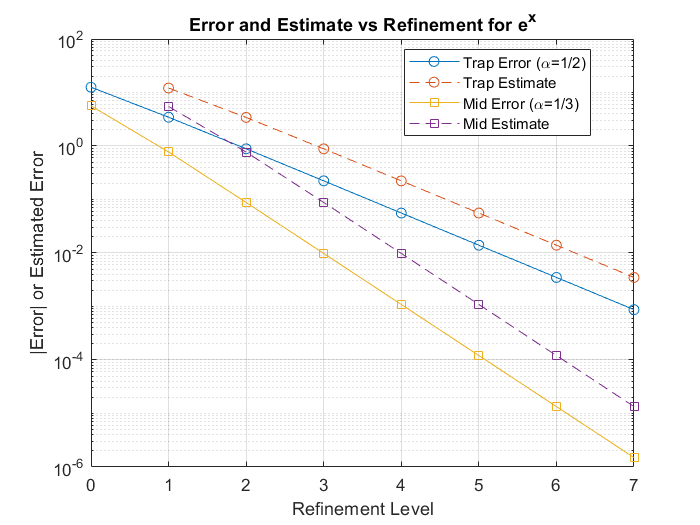

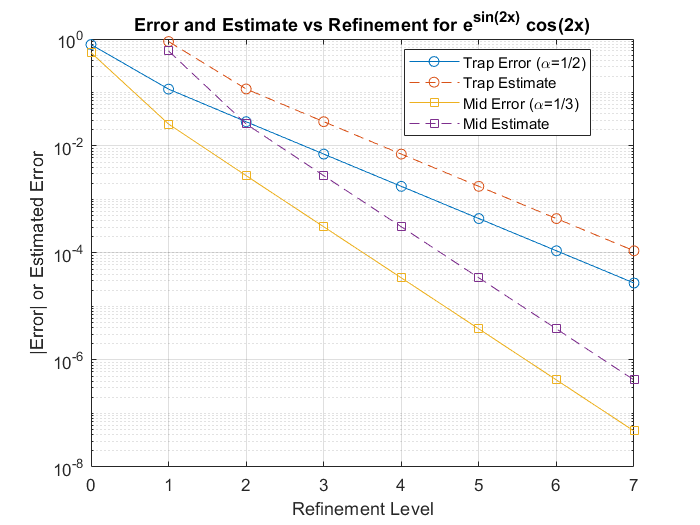

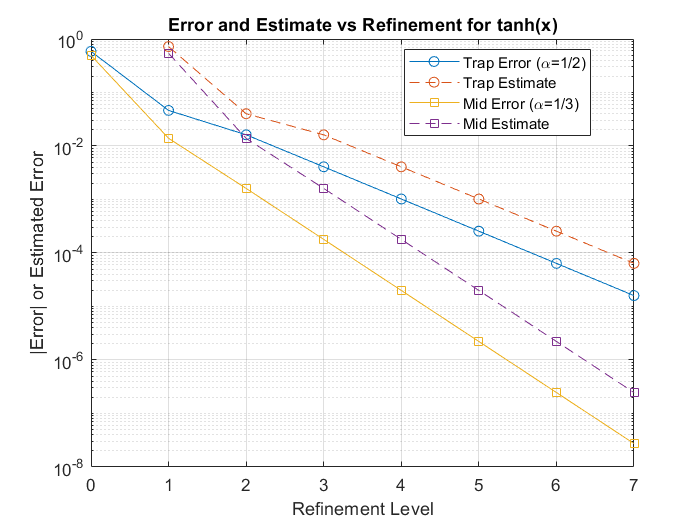

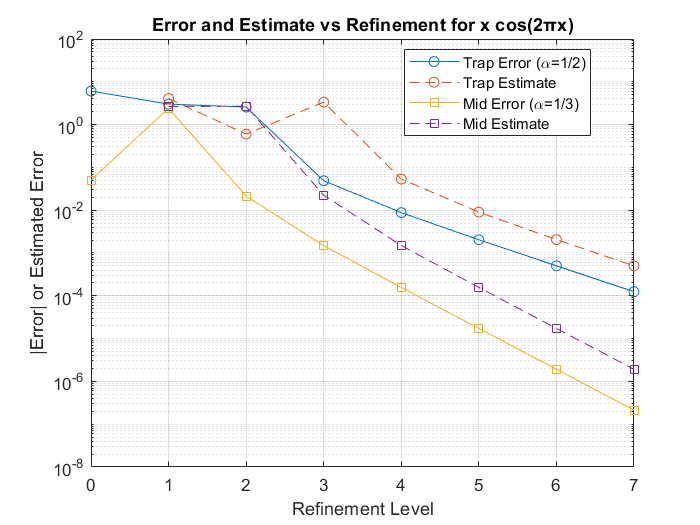

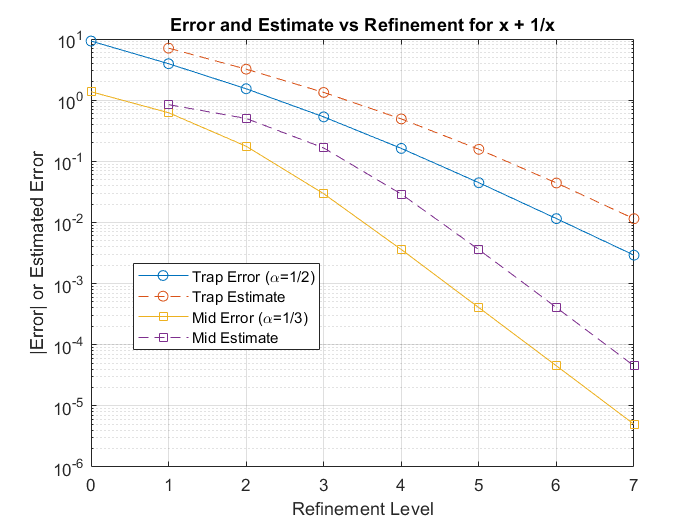

% Define functions and exact integrals
functions = {
    @(x) exp(x),                        0, 3,              exp(3) - 1,                         'e^x';
    @(x) exp(sin(2*x)).*cos(2*x),       0, pi/3,           0.5 * (-1 + exp(sqrt(3)/2)),        'e^{sin(2x)} cos(2x)';
    @(x) tanh(x),                      -2, 1,              log(cosh(1)/cosh(2)),               'tanh(x)';
    @(x) x .* cos(2*pi*x),              0, 3.5,            -1/(2*pi^2),                        'x cos(2πx)';
    @(x) x + 1./x,                      0.1, 2.5,          (2.5^2 - 0.1^2)/2 + log(2.5/0.1),    'x + 1/x'
};

num_refinements = 15;

for k = 1:size(functions,1)
    f = functions{k,1};
    a = functions{k,2};
    b = functions{k,3};
    true_val = functions{k,4};
    label = functions{k,5};

    n = 1;
    H = (b - a) / n;
    mesh = linspace(a, b, n+1);

    % Run adaptive trapezoidal (alpha = 1/2)
    [trap_ints, trap_errs, trap_estims] = trapadaptive(f, mesh, H, n, true_val, num_refinements);

    % Run adaptive midpoint (alpha = 1/3)
    [mid_ints, mid_errs, mid_estims] = midadaptive(f, mesh, H, n, true_val, num_refinements);

    refinements = 0:num_refinements;

 

        %% Plot Combined: Absolute Errors + Estimated Errors
    figure;
    semilogy(refinements, abs(trap_errs), '-o', ...
             refinements(2:end), abs(trap_estims), '--o', ...
             refinements, abs(mid_errs), '-s', ...
             refinements(2:end), abs(mid_estims), '--s');

    xlabel('Refinement Level');
    ylabel('|Error| or Estimated Error');
    title(['Error and Estimate vs Refinement for ', label]);
    legend({'Trap Error (\alpha=1/2)', 'Trap Estimate', ...
            'Mid Error (\alpha=1/3)', 'Mid Estimate'}, ...
            'Location', 'best');
    grid on;

    % Save combined plot
    filename = ['adaptive_combined_' regexprep(label, '[^a-zA-Z0-9]', '_') '.png'];
    saveas(gcf, filename);

end